# **Distributed-parameter transducer model**

# **for the stepped amplitude transformer**

**2023-01-03 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

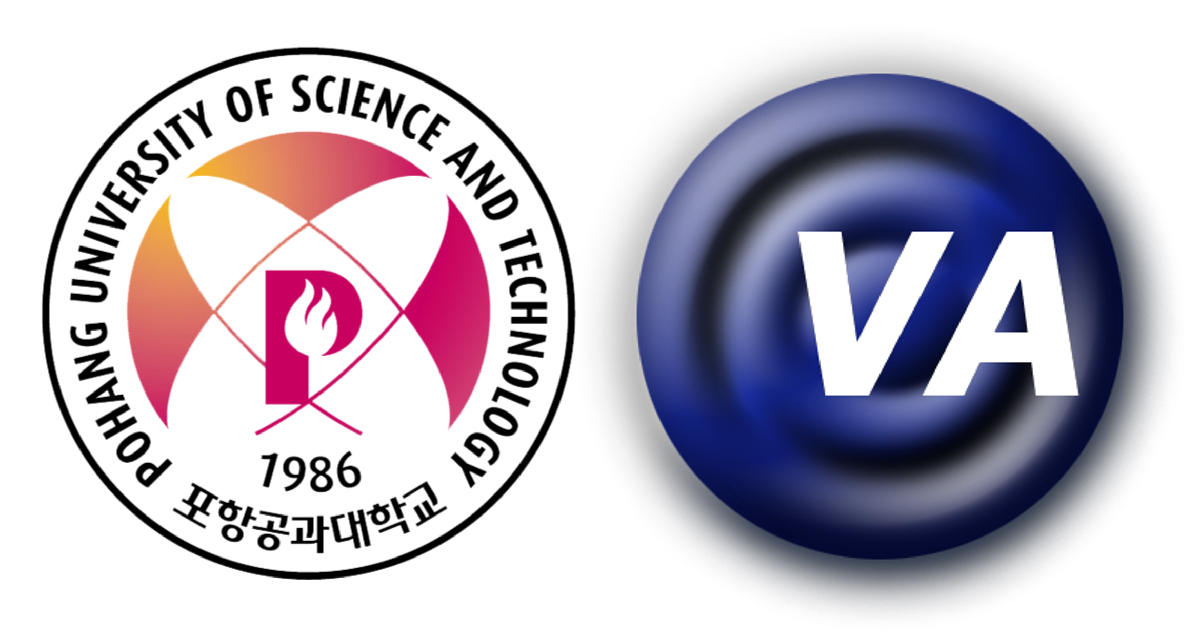

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Define the simulation frequency
% f = 75e3;   % 75 [kHz]
syms f

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');

% Load the plate's impedance
[~,Z_p_wo_steps] = import_impedance('D -230725 - Stepped-plate impedance w.o. steps.txt');
[~,Z_p_w_steps] = import_impedance('D -230725 - Stepped-plate impedance w. steps.txt');

freq_r = 75960;

% Define the structure
n_start = 1;    % Start index of node;
n_end   = 5;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    4
The number of nodes:       5


e_piezo = 2;  % Index of piezoelectric bar

% Initialize the symbols for material properties and design parameters of elements

% Mechanical
rho = sym('rho_%d', [1 n_end]); % Density
E   = sym('E_%d',   [1 n_end]); % Young's modulus
nu  = sym('nu_%d',  [1 n_end]); % Poisson ratio
c   = sym('c_%d',   [1 n_end]); % Longitudinal wave speed
k   = sym('k_%d',   [1 n_end]); % Longitudinal wave number
l   = sym('l_%d',   [1 n_end]); % Length of element
A   = sym('A_%d',   [1 n_end]); % Area of element
Z_p = sym('Z_p');               % Mehcanical impedance of plate

% Electircal
eps_33  = sym('eps_33');        % Dielectric constant, eps_33
N_piezo = sym('N_piezo');       % Number of Piezo

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33


The effort and flow variable vectors are $\mathbf{F}=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $\mathbf{u}=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end]).';
u   = sym('u_%d',[1 n_end]).';
V   = sym('V');


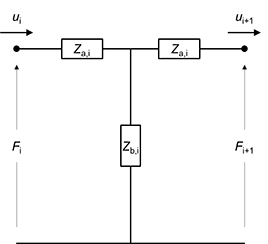

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

By the KCL,


$$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]$$


% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

% rho(1:n_start-1)    = [];
% c(1:n_start-1)      = [];
% k(1:n_start-1)      = [];
% l(1:n_start-1)      = [];
% A(1:n_start-1)      = [];


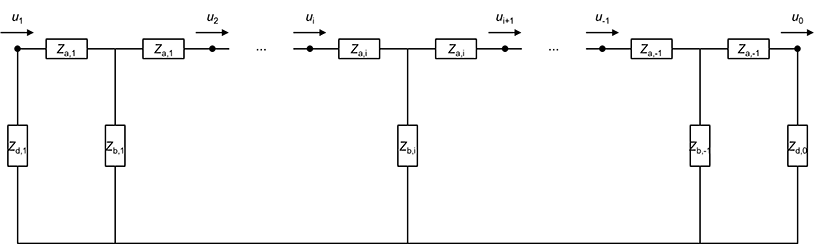

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $\mathbf{F}=\mathbf{Z} \cdot \mathbf{u}=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,-1}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end n_end]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i-1:i));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end-1) + Z_d(n_end);

Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} Z_{d,1}-\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{d,5}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

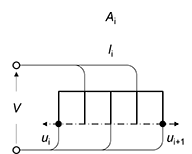

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

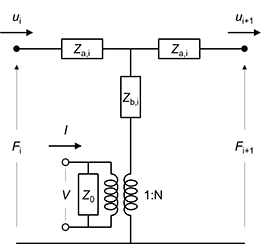

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}+NV\cr
-F_{i+1}-NV\cr
}
\right]$where $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}$

N = N_piezo*A(e_piezo)*d_33*E(e_piezo)/l(e_piezo);

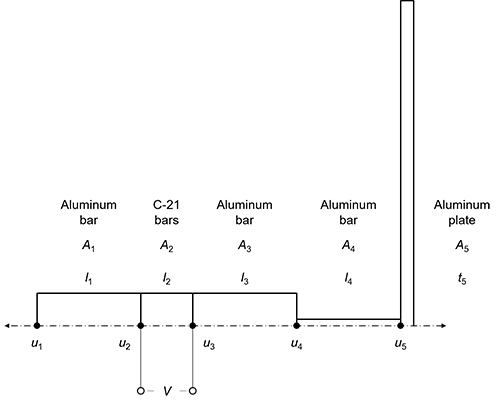

**Figure 5** Typical stepped-plate transducer

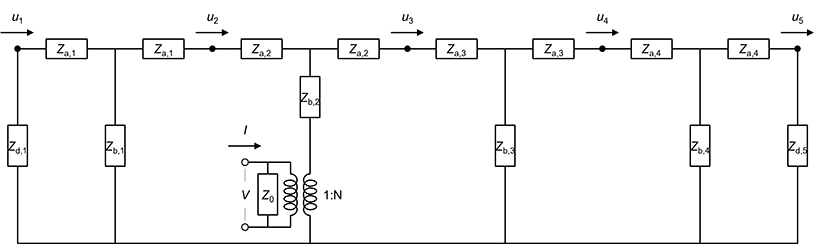

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 \cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} \cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,4}}+Z_{\rm{d,5}} \cr
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
}
\right]

=

\left[
\matrix{
0\cr
NV\cr
-NV\cr
0\cr
0\cr
}
\right]$$


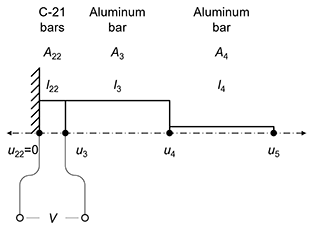

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

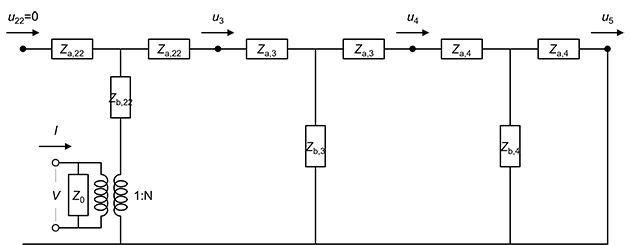

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% For the stepped horn

% Applying the volume conditions as material properties

% Define the bounrady conditions of both ends
Z = subs(Z, [Z_d(n_start) Z_d(n_end)], [0 Z_p]);
Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
Z

$$Z = \begin{array}{l} \left(\begin{array}{ccccc} -\sigma_{8} & \sigma_{4} & 0 & 0 & 0\\ \sigma_{4} & -\sigma_{8}-\sigma_{7} & \sigma_{3} & 0 & 0\\ 0 & \sigma_{3} & -\sigma_{7}-\sigma_{6} & \sigma_{2} & 0\\ 0 & 0 & \sigma_{2} & -\sigma_{6}-\sigma_{5} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & Z_{p}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{4}\,c_{4}\,\rho_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}\\ \sigma_{2}=\frac{A_{3}\,c_{3}\,\rho_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}\\ \sigma_{3}=\frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}\\ \sigma_{4}=\frac{A_{1}\,c_{1}\,\rho_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}\\ \sigma_{5}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{6}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{7}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{8}=A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i} \end{array}$$

detZ = det(Z)

Define the boundary conditions

- Velocity at node 22, $u_{22}=0$

% u = subs(u, u(n_start), 0);
u(1:n_start-1)  = [];
u

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4}\\ u_{5} \end{array}\right)$$

Define the force conditions

- Force at node 22, $F_{22}=NV$

- Force at node 3, $F_{3}=-NV$

F = subs(F, F(1:e_piezo-1), zeros(e_piezo-1,1));
F = subs(F, F(e_piezo), N*V);
F = subs(F, F(e_piezo+1), - N*V);
F = subs(F, F(e_piezo+2:end), zeros(n_end - e_piezo - 1,1));
F(1:n_start-1)  = [];
F

$$F = \left(\begin{array}{c} 0\\ \frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ -\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}}\\ 0\\ 0 \end{array}\right)$$

Solve $\mathbf{Z}\cdot \mathbf{u}=\mathbf{F}$

eqn = Z*u == F

$$eqn = \begin{array}{l} \left(\begin{array}{c} -A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{2}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}=0\\ -u_{2}\,\left(A_{1}\,c_{1}\,\rho_{1}\,\cot\left(k_{1}\,l_{1}\right)\,\mathrm{i}+\sigma_{3}\right)+\frac{A_{1}\,c_{1}\,\rho_{1}\,u_{1}\,\mathrm{i}}{\sin\left(k_{1}\,l_{1}\right)}+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}=\sigma_{4}\\ -u_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{4}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}=-\sigma_{4}\\ -u_{4}\,\left(\sigma_{2}+\sigma_{1}\right)+\frac{A_{3}\,c_{3}\,\rho_{3}\,u_{3}\,\mathrm{i}}{\sin\left(k_{3}\,l_{3}\right)}+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{5}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0\\ u_{5}\,\left(Z_{p}-\sigma_{1}\right)+\frac{A_{4}\,c_{4}\,\rho_{4}\,u_{4}\,\mathrm{i}}{\sin\left(k_{4}\,l_{4}\right)}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{4}\,c_{4}\,\rho_{4}\,\cot\left(k_{4}\,l_{4}\right)\,\mathrm{i}\\ \sigma_{2}=A_{3}\,c_{3}\,\rho_{3}\,\cot\left(k_{3}\,l_{3}\right)\,\mathrm{i}\\ \sigma_{3}=A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}\\ \sigma_{4}=\frac{A_{2}\,E_{2}\,N_{\mathrm{piezo}}\,V\,d_{33}}{l_{2}} \end{array}$$

% for i=2:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i-1),u(i));
% end
% for i=1:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i),u(i));
% end
% u = Z(2:4,2:4)\F(2:4)
u = Z\F

u1 = u(1);
u2 = u(2);
u3 = u(3);

u5 = u(5);

R31 = u3/u1

% Compute simplified symbolic expression
simplifiedExpr = simplify(R31)


% [n,d] = numden(u3);
% eqn = Z*u == F
% u(2) = solve(eqn(1),u(2))
% eqn1 = Z*u == F
% u(3) = solve(eqn1(2),u(3))
% eqn2 = Z*u == F
% u(4) = solve(eqn2(3),u(4))

u = subs(u, A(3), A(2));
u = subs(u, c(4), c(3));
u = subs(u, k(4), k(3));
u = subs(u, rho(4), rho(3))

Substituting the numerical geometric dimensions and material properties into the symbols,

u = subs(u, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
% u = subs(u, [A(2) A(4)],        [pi*7e-3^2  pi*1.5e-3^2]);
% u = subs(u, [l(1) l(2) l(3) l(4)],  [12e-3  4e-3    13.9e-3 15.29e-3]);
u = subs(u, [l(1) l(2) l(3) l(4)],  [12e-3  4e-3    11.5e-3 10.9e-3]);

u = subs(u, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
u = subs(u, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
u = subs(u, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
u = subs(u, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
u = subs(u, d_33,               mat.d33('C-21'));
u = subs(u, N_piezo,            4);

u = subs(u, V, 10);
u

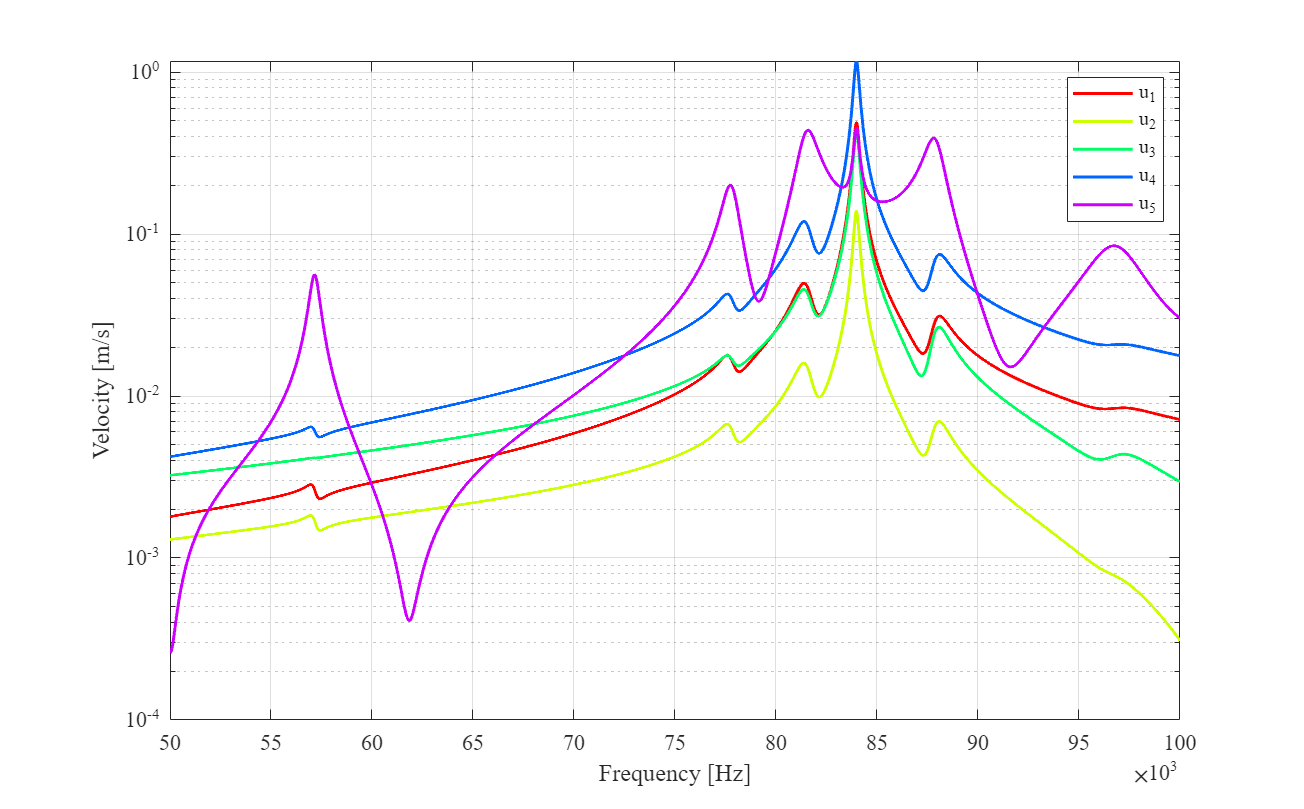

tic
fr_u = symfun(u,f);
fr_u_num = matlabFunction(fr_u);
freq = 50e3:10:100e3;
% u_num = fr_u_num(freq);
u_num_w = fr_u_num(freq,interp1(freq, Z_p_w_steps,freq));
% semilogy(freq, abs(u_num))
% fplot(abs(fr_u(f)),[50e3 100e3])
createfigure_fr(freq, abs(u_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")

toc

Elapsed time is 2.720096 seconds.


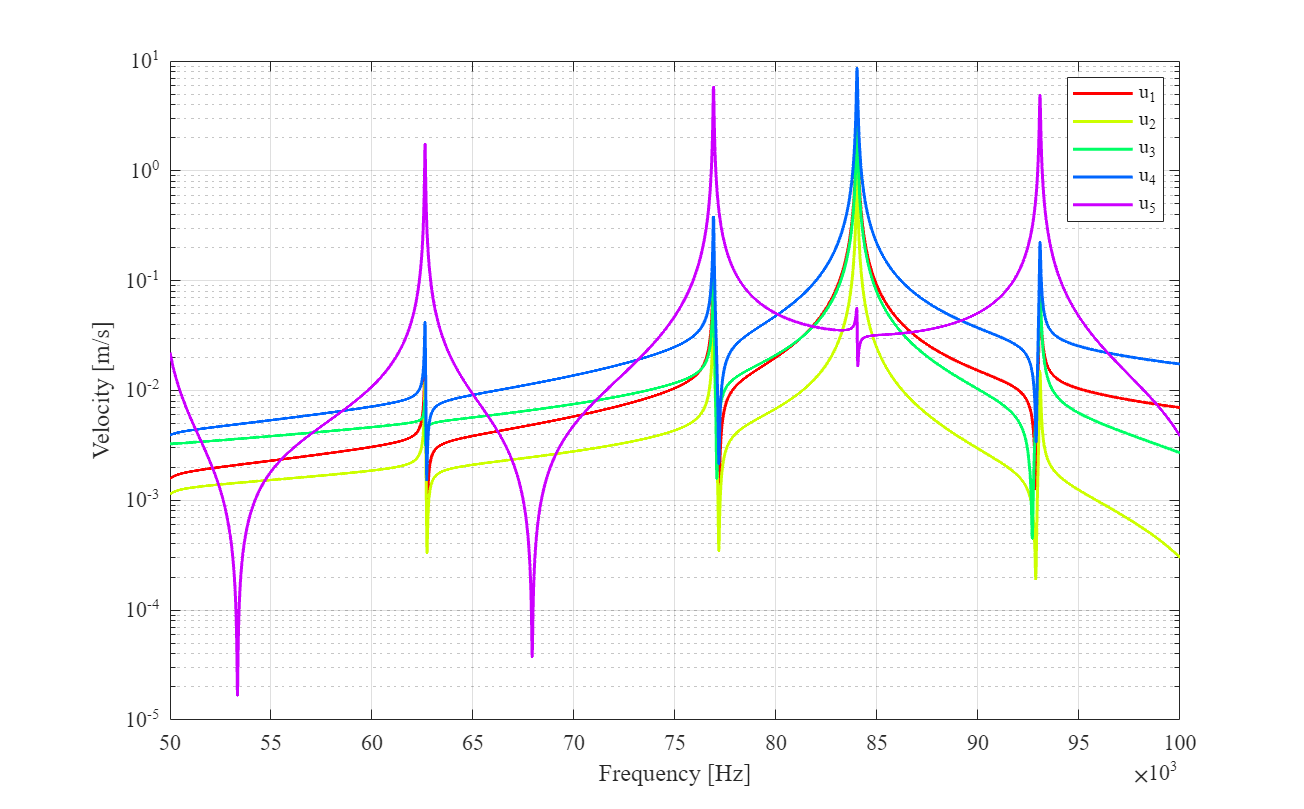

tic
u_num_wo = fr_u_num(freq,interp1(freq, Z_p_wo_steps,freq));
createfigure_fr(freq, abs(u_num_wo)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")

toc

Elapsed time is 0.407590 seconds.


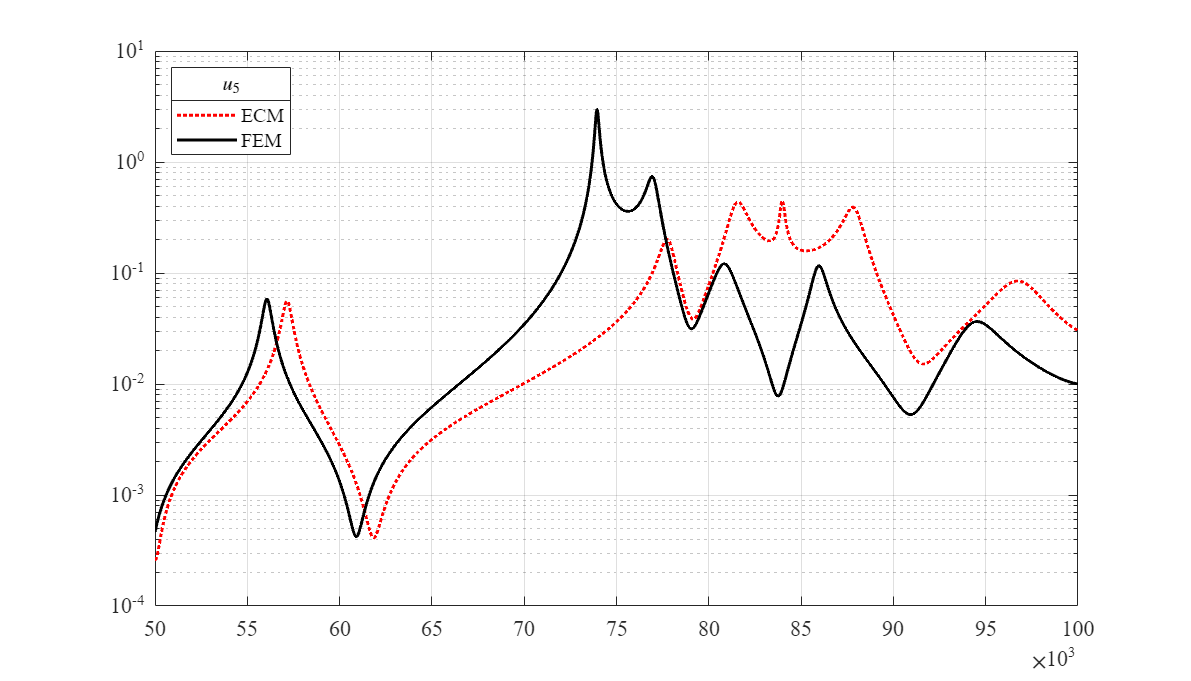

u_OBS_wo    = import_COMSOL('D -230725 - OBS rework by WJ w.o. Steps.txt');
u_OBS_w     = import_COMSOL('D -230725 - OBS rework by WJ w. Steps.txt');

createfigure_fr_comp3(freq, abs(u_num_w(5,:))', u_OBS_w.freq, u_OBS_w.v5, ...
    'northwest',"$u_5$","ECM","FEM",'','','linear','log')

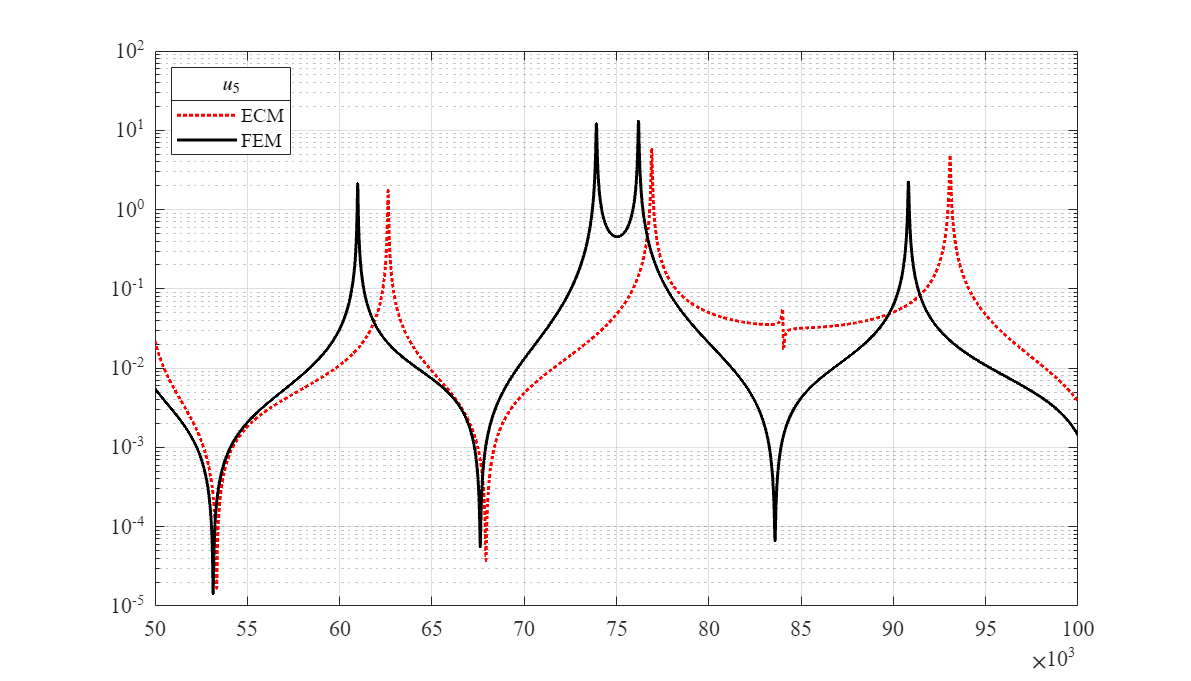

createfigure_fr_comp3(freq, abs(u_num_wo(5,:))', u_OBS_wo.freq, u_OBS_wo.v5, ...
    'northwest',"$u_5$","ECM","FEM",'','','linear','log')


% createfigure_fr_comp(freq, abs(u_num_w(5,:))', u_OBS_w.freq, u_OBS_w.v5, '', "u_5", ...
%     'Frequency [Hz]','Velocity [m/s]','linear','log')
% 
% createfigure_fr_comp(freq, abs(u_num_wo(5,:))', u_OBS_wo.freq, u_OBS_wo.v5, '', "u_5", ...
%     'Frequency [Hz]','Velocity [m/s]','linear','log')

detZ = subs(detZ, A(3), A(2));
detZ = subs(detZ, c(4), c(3));
detZ = subs(detZ, k(4), k(3));
detZ = subs(detZ, rho(4), rho(3))

Substituting the numerical geometric dimensions and material properties into the symbols,

detZ = subs(detZ, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
% detZ = subs(detZ, [A(2) A(4)],        [pi*7e-3^2  pi*1.5e-3^2]);
detZ = subs(detZ, [l(1) l(2)],  [12e-3  4e-3]);

detZ = subs(detZ, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
detZ = subs(detZ, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
detZ = subs(detZ, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
detZ = subs(detZ, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
detZ = subs(detZ, d_33,               mat.d33('C-21'));
detZ = subs(detZ, N_piezo,            4);

detZ = subs(detZ, V, 10);
detZ

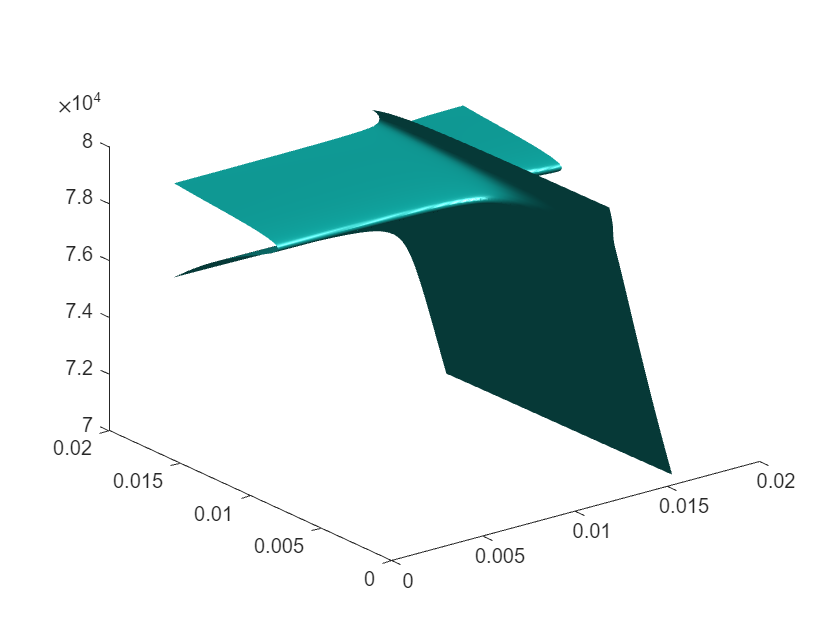

tic
fr_detZ = symfun(detZ,[f,l(3),l(4),Z_p]);
fr_detZ_num = matlabFunction(fr_detZ);
% freq = 50e3:10:100e3;
% u_num = fr_u_num(freq);

lambda4 = abs(mat.v3('Aluminum'))/freq_r/4;
% l3 = 1e-3:1e-3:lambda_4;
% l4 = 1e-3:1e-3:lambda_4;
% detZ_num_w = fr_detZ_num(freq,l3,l4,interp1(freq, Z_p_w_steps,freq));

% [freq, l3, l4] = meshgrid(1e-4:1e-4:lambda_4, 1e-4:1e-4:lambda_4);
% detZ_num_w = fr_detZ_num(freq_r,l3,l4,interp1(freq, Z_p_w_steps,freq_r));
% contourf(l3, l4, imag(detZ_num_w));

% [l3, l4, freq] = meshgrid(1e-4:1e-4:lambda_4, 1e-4:1e-4:lambda_4,50e3:10:100e3);
[l3, l4, freq] = meshgrid(1e-3:1e-4:lambda4, 1e-3:1e-4:lambda4,70e3:100:80e3);
l3Count = size(l3,2);
l4Count = size(l4,1);
freqCount = size(freq,3);
freq1 = 50e3:10:100e3;
detZ_num_w = fr_detZ_num(freq,l3,l4,interp1(freq1, Z_p_w_steps,freq));
figure
isosurface(l3, l4, freq, imag(detZ_num_w),0)


% contourf(l3, l4, imag(detZ_num_w));


% % semilogy(freq, abs(u_num))
% % fplot(abs(fr_u(f)),[50e3 100e3])
% createfigure_fr(freq, abs(u_num_w)',["u_1" "u_2" "u_3" "u_4" "u_5"],"Frequency [Hz]","Velocity [m/s]","linear","log")
toc

Elapsed time is 4.535969 seconds.


u5 = subs(u5, A(3), A(2));
u5 = subs(u5, c(4), c(3));
u5 = subs(u5, k(4), k(3));
u5 = subs(u5, rho(4), rho(3))

% Substituting the numerical geometric dimensions and material properties into the symbols,
u5 = subs(u5, [A(1) A(2) A(4)],       [pi*7e-3^2  pi*7e-3^2   pi*0.75e-3^2]);
u5 = subs(u5, [l(1) l(2)],  [12e-3  4e-3]);

u5 = subs(u5, [E(1) E(2) E(3)],       [mat.Y33('Stainless Steel') mat.Y33('C-21')        mat.Y33('Aluminum')]);
u5 = subs(u5, [c(1) c(2) c(3)],        [mat.v3('Stainless Steel') mat.v3('C-21')         mat.v3('Aluminum')]);
u5 = subs(u5, [k(1) k(2) k(3)],        [2*pi*f/mat.v3('Stainless Steel') 2*pi*f/mat.v3('C-21')  2*pi*f/mat.v3('Aluminum')]);
u5 = subs(u5, [rho(1) rho(2) rho(3)],    [mat.rho('Stainless Steel')   mat.rho('C-21')        mat.rho('Aluminum')]);
u5 = subs(u5, d_33,               mat.d33('C-21'));
u5 = subs(u5, N_piezo,            4);

u5 = subs(u5, V, 10);
u5


fr_u5 = symfun(u5,[f,l(3),l(4),Z_p]);
fr_u5_num = matlabFunction(fr_u5);

u5_num_w = fr_u5_num(freq,l3,l4,interp1(freq1, Z_p_w_steps,freq));
u5_num_w_sq = squeeze(reshape(u5_num_w, [],1,freqCount));
% semilogy(squeeze(freq(1,1,:)),abs(u5_num_w_sq))

% [l3_water, freq_water] = meshgrid(1e-3:1e-3:lambda4,70e3:100:80e3);
% l3_water_sq = repmat(l3_water, 1, l4Count);
% freq_water_sq = repmat(freq_water, 1, l4Count);
% 
% waterfall(l3_water_sq',freq_water_sq',log10(abs(u5_num_w_sq)))

[l4_water, freq_water] = meshgrid(1e-3:1e-3:lambda4,70e3:100:80e3);
l4_waterCount = size(l4_water,2);


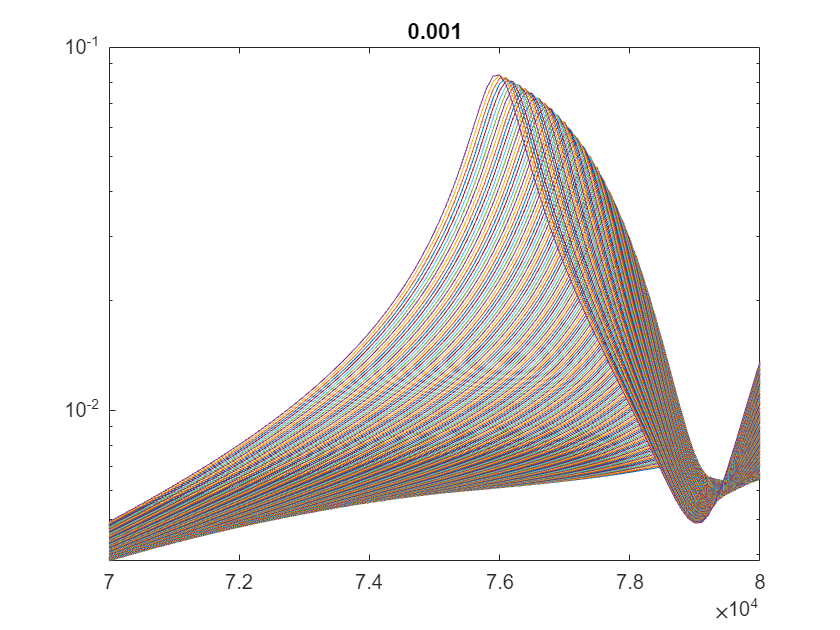

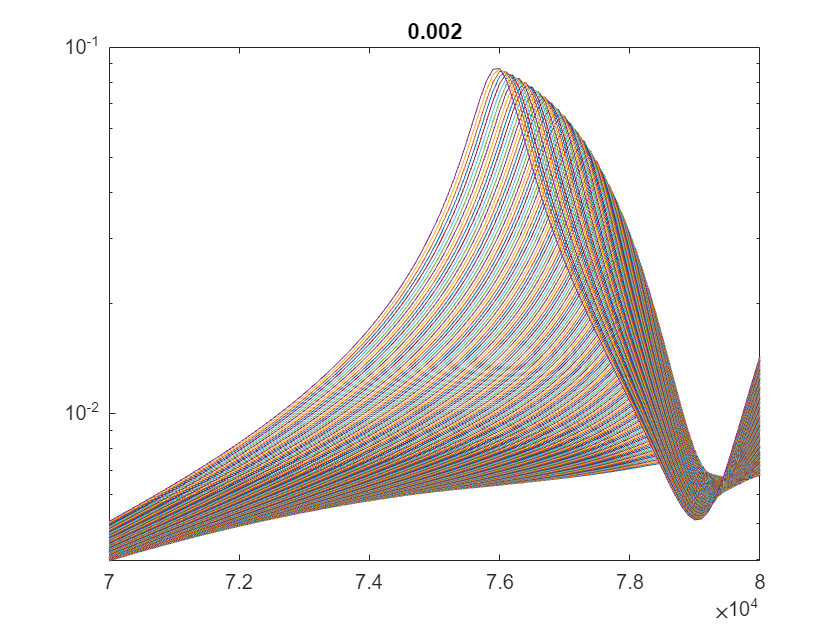

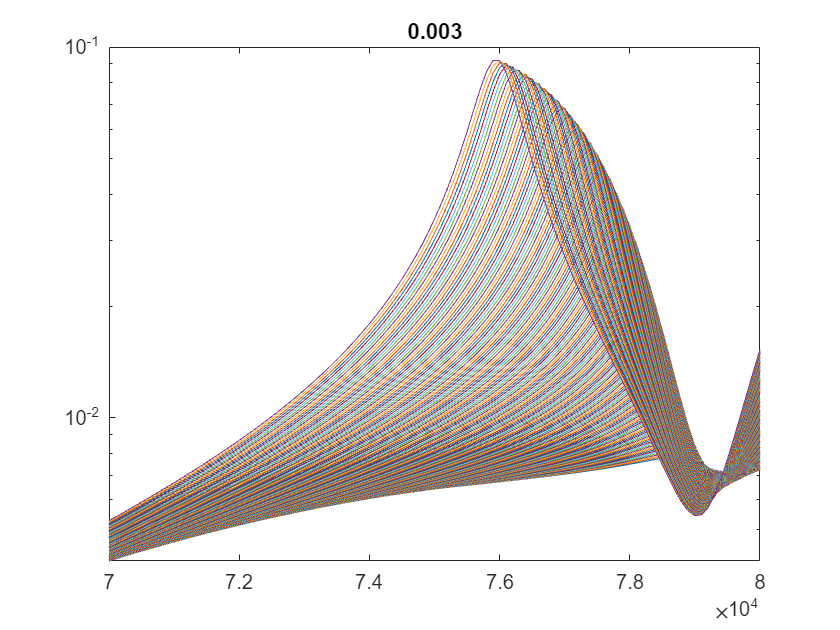

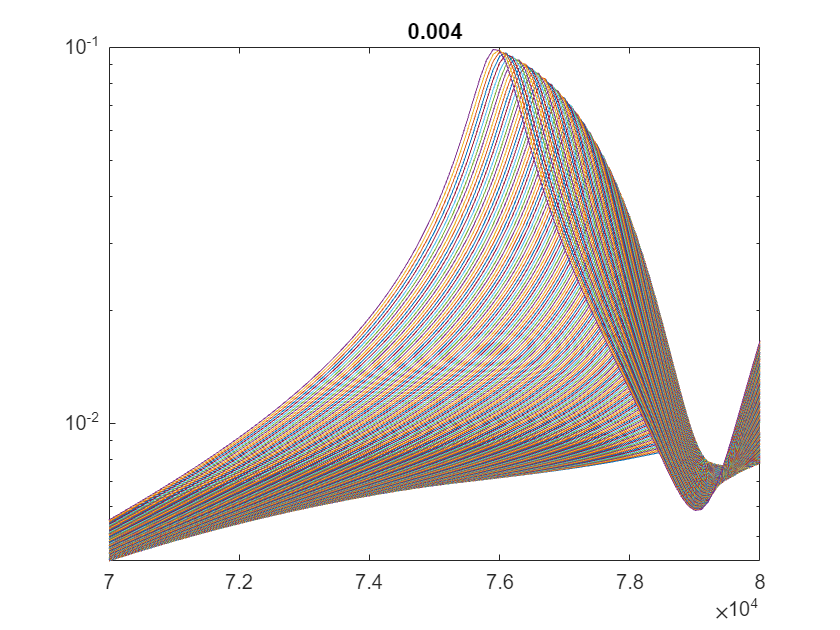

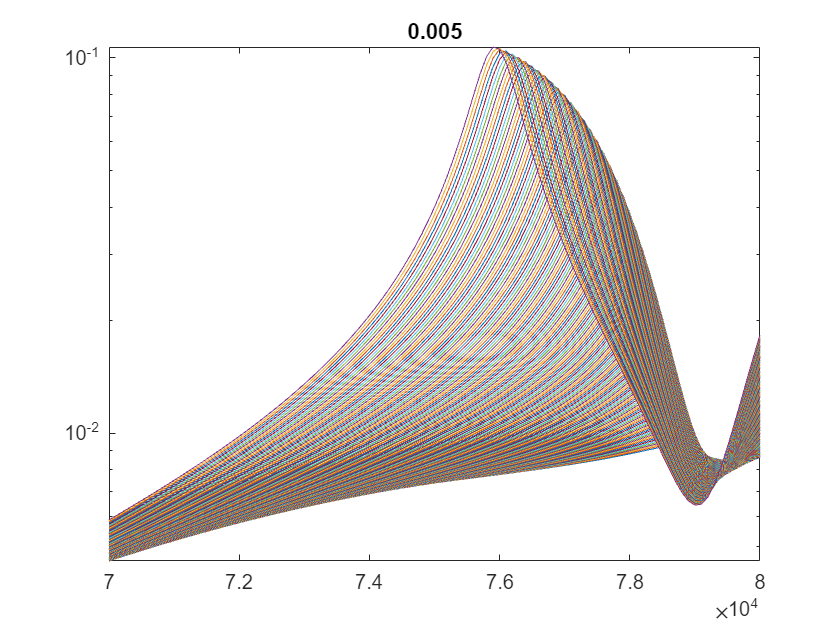

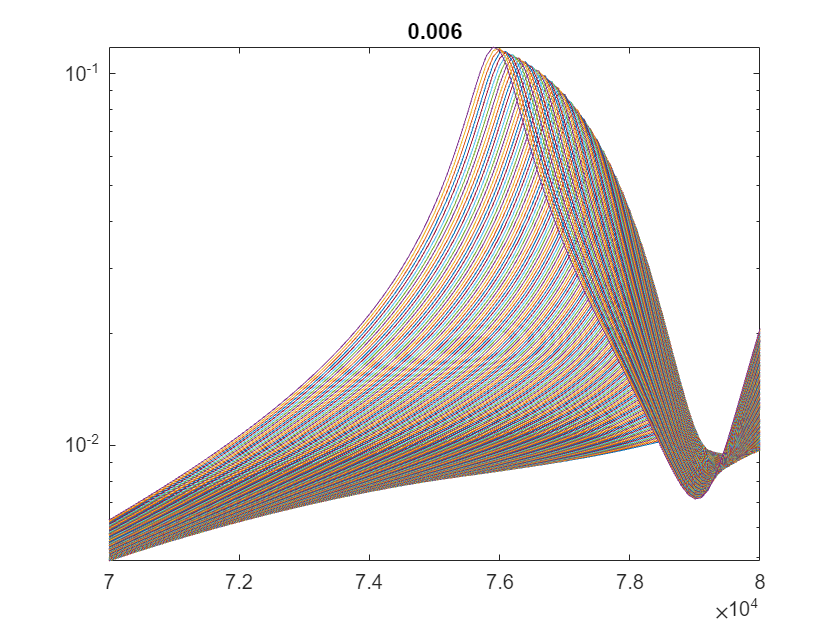

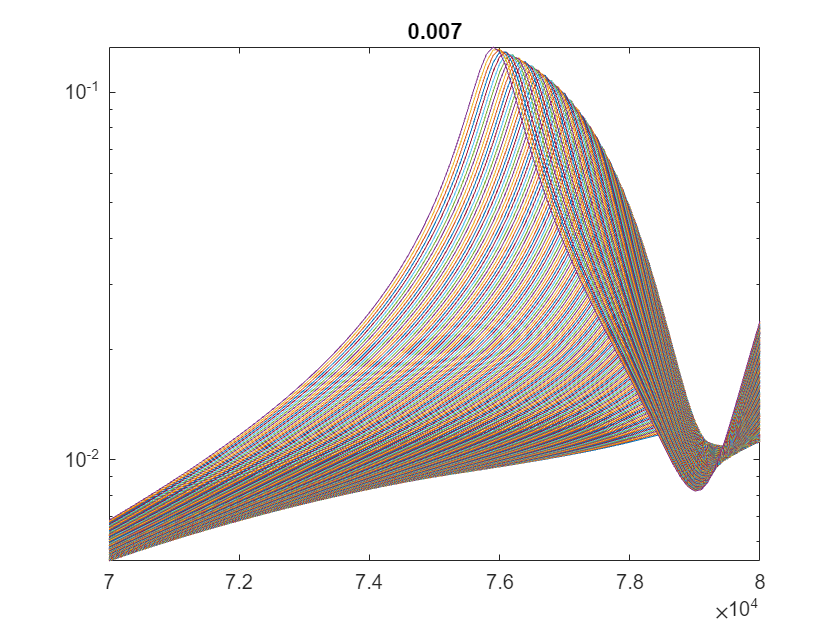

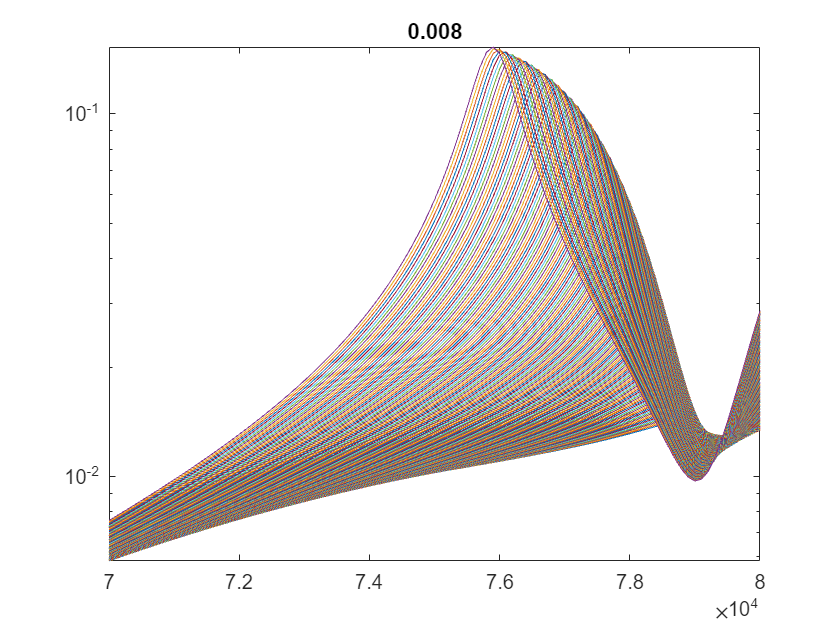

ans = 1200

ans = 0.4552

ans = 1200

ans = 0.4589

ans = 1200

ans = 0.4606

ans = 1200

ans = 0.4604

ans = 1200

ans = 0.4584

ans = 1300

ans = 0.4582

ans = 1300

ans = 0.4658

ans = 1300

ans = 0.4714

ans = 1300

ans = 0.4747

ans = 1300

ans = 0.4757

ans = 1300

ans = 0.4744

ans = 1300

ans = 0.4711

ans = 1400

ans = 0.4793

ans = 1400

ans = 0.4855

ans = 1400

ans = 0.4891

ans = 1400

ans = 0.4900

ans = 1400

ans = 0.4883

ans = 1500

ans = 0.4878

ans = 1500

ans = 0.4961

ans = 1500

ans = 0.5014

ans = 1500

ans = 0.5036

ans = 1500

ans = 0.5027

ans = 1600

ans = 0.4991

ans = 1600

ans = 0.5083

ans = 1600

ans = 0.5141

ans = 1600

ans = 0.5164

ans = 1600

ans = 0.5151

ans = 1700

ans = 0.5135

ans = 1700

ans = 0.5223

ans = 1700

ans = 0.5272

ans = 1700

ans = 0.5280

ans = 1700

ans = 0.5249

ans = 1800

ans = 0.5302

ans = 1800

ans = 0.5369

ans = 1800

ans = 0.5390

ans = 1800

ans = 0.5365

ans = 1900

ans = 0.5388

ans = 1900

ans = 0.5463

ans = 1900

ans = 0.5486

ans = 1900

ans = 0.5459

ans = 2000

ans = 0.5487

ans = 2000

ans = 0.5556

ans = 2000

ans = 0.5569

ans = 2000

ans = 0.5527

ans = 2100

ans = 0.5592

ans = 2100

ans = 0.5642

ans = 2100

ans = 0.5630

ans = 2200

ans = 0.5608

ans = 2200

ans = 0.5689

ans = 2200

ans = 0.5703

ans = 2200

ans = 0.5652

ans = 2300

ans = 0.5721

ans = 2300

ans = 0.5755

ans = 2300

ans = 0.5717

ans = 2400

ans = 0.5747

ans = 2400

ans = 0.5791

ans = 2400

ans = 0.5760

ans = 2500

ans = 0.5769

ans = 2500

ans = 0.5816

ans = 2500

ans = 0.5782

ans = 2600

ans = 0.5789

ans = 2600

ans = 0.5829

ans = 2600

ans = 0.5784

ans = 2700

ans = 0.5804

ans = 2700

ans = 0.5827

ans = 2700

ans = 0.5762

ans = 2800

ans = 0.5808

ans = 2800

ans = 0.5805

ans = 2900

ans = 0.5739

ans = 2900

ans = 0.5796

ans = 2900

ans = 0.5756

ans = 3000

ans = 0.5742

ans = 3000

ans = 0.5756

ans = 3000

ans = 0.5673

ans = 3100

ans = 0.5718

ans = 3100

ans = 0.5680

ans = 3200

ans = 0.5648

ans = 3200

ans = 0.5654

ans = 3100

ans = 0.5570

ans = 3200

ans = 0.5642

ans = 3200

ans = 0.5613

ans = 3300

ans = 0.5627

ans = 3300

ans = 0.5635

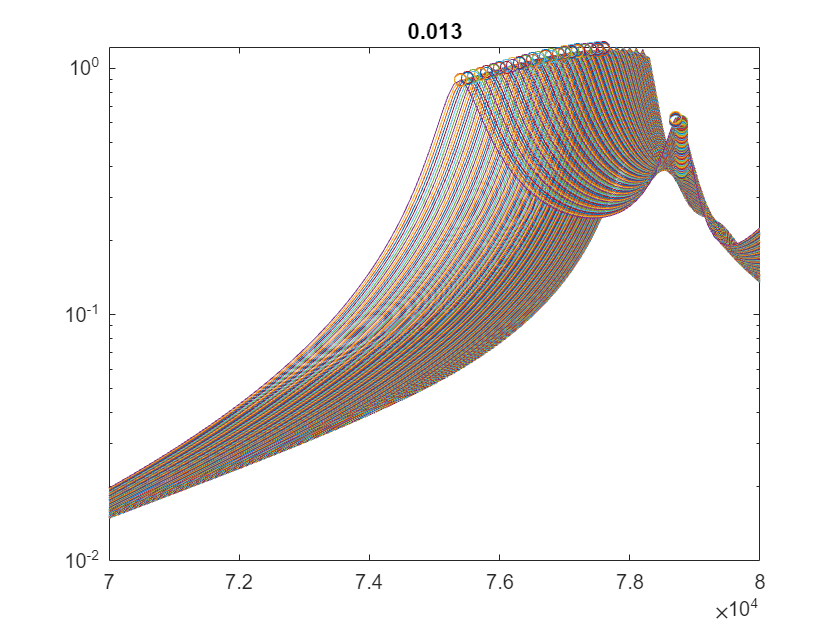

ans = 3000

ans = 0.4451

ans = 3000

ans = 0.4493

ans = 3000

ans = 0.4505

ans = 3000

ans = 0.4490

ans = 3000

ans = 0.4450

ans = 3000

ans = 0.4390

ans = 3000

ans = 0.4314

ans = 3000

ans = 0.4228

ans = 3000

ans = 0.4134

ans = 3000

ans = 0.4037

ans = 3000

ans = 0.3939

ans = 3000

ans = 0.3843

ans = 3100

ans = 0.3940

ans = 3100

ans = 0.4199

ans = 3100

ans = 0.4471

ans = 3100

ans = 0.4752

ans = 3100

ans = 0.5037

ans = 3100

ans = 0.5320

ans = 3100

ans = 0.5590

ans = 3100

ans = 0.5838

ans = 3100

ans = 0.6053

ans = 3100

ans = 0.6225

ans = 3100

ans = 0.6348

ans = 3100

ans = 0.6418

ans = 3100

ans = 0.6437

ans = 3100

ans = 0.6408

ans = 3100

ans = 0.6339

ans = 3100

ans = 0.6238

ans = 3100

ans = 0.6115

ans = 3100

ans = 0.5975

ans = 3000

ans = 0.5838

ans = 3100

ans = 0.5715

ans = 3100

ans = 0.6137

ans = 3100

ans = 0.6576

ans = 3100

ans = 0.7020

ans = 3100

ans = 0.7455

ans = 3100

ans = 0.7863

ans = 3100

ans = 0.8224

ans = 3100

ans = 0.8519

ans = 3100

ans = 0.8731

ans = 3000

ans = 0.8851

ans = 3000

ans = 0.8913

ans = 3000

ans = 0.8894

ans = 3000

ans = 0.8806

ans = 3000

ans = 0.8664

ans = 3000

ans = 0.8483

ans = 3000

ans = 0.8277

ans = 3100

ans = 0.8523

ans = 3100

ans = 0.9136

ans = 3000

ans = 0.9752

ans = 3000

ans = 1.0353

ans = 3000

ans = 1.0880

ans = 3000

ans = 1.1298

ans = 3000

ans = 1.1581

ans = 3000

ans = 1.1716

ans = 3000

ans = 1.1706

ans = 2900

ans = 1.1586

ans = 2900

ans = 1.1432

ans = 2900

ans = 1.1206

ans = 3000

ans = 1.1172

ans = 3000

ans = 1.1998

ans = 3000

ans = 1.2758

ans = 3000

ans = 1.3396

ans = 2900

ans = 1.3978

ans = 2900

ans = 1.4388

ans = 2900

ans = 1.4584

ans = 2900

ans = 1.4568

ans = 2900

ans = 1.4365

ans = 2800

ans = 1.4023

ans = 2900

ans = 1.3978

ans = 2900

ans = 1.5002

ans = 2900

ans = 1.5884

ans = 2900

ans = 1.6544

ans = 2900

ans = 1.6916

ans = 2800

ans = 1.7160

ans = 2800

ans = 1.7186

ans = 2800

ans = 1.6963

ans = 2800

ans = 1.6538

ans = 2900

ans = 1.7313

ans = 2800

ans = 1.8306

ans = 2800

ans = 1.9088

ans = 2800

ans = 1.9504

ans = 2800

ans = 1.9528

ans = 2800

ans = 1.9184

ans = 2700

ans = 1.8885

ans = 2800

ans = 1.9765

ans = 2800

ans = 2.0711

ans = 2800

ans = 2.1217

ans = 2700

ans = 2.1363

ans = 2700

ans = 2.1397

ans = 2700

ans = 2.1047

ans = 2800

ans = 2.1609

ans = 2800

ans = 2.2343

ans = 2700

ans = 2.2953

ans = 2700

ans = 2.3182

ans = 2700

ans = 2.2900

ans = 2800

ans = 2.2728

ans = 2700

ans = 2.3577

ans = 2700

ans = 2.4354

ans = 2700

ans = 2.4526

ans = 2700

ans = 2.4108

ans = 2800

ans = 2.4100

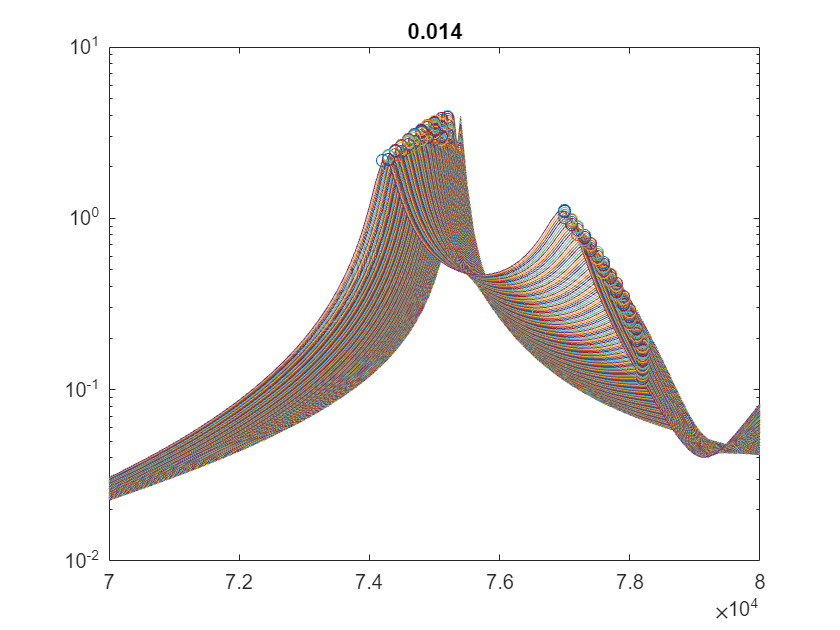

ans = 5800

ans = 0.1540

ans = 5800

ans = 0.1564

ans = 5800

ans = 0.1579

ans = 5900

ans = 0.1583

ans = 5900

ans = 0.1578

ans = 5900

ans = 0.1565

ans = 5900

ans = 0.1543

ans = 5900

ans = 0.1516

ans = 5900

ans = 0.1485

ans = 5900

ans = 0.1450

ans = 5900

ans = 0.1414

ans = 5900

ans = 0.1377

ans = 5900

ans = 0.1339

ans = 5900

ans = 0.1303

ans = 5900

ans = 0.1268

ans = 5900

ans = 0.1234

ans = 5900

ans = 0.1201

ans = 5900

ans = 0.1171

ans = 6000

ans = 0.1210

ans = 6000

ans = 0.1277

ans = 6000

ans = 0.1349

ans = 6000

ans = 0.1425

ans = 6000

ans = 0.1507

ans = 6000

ans = 0.1592

ans = 6000

ans = 0.1682

ans = 6000

ans = 0.1774

ans = 6000

ans = 0.1869

ans = 5900

ans = 0.1965

ans = 5900

ans = 0.2061

ans = 5900

ans = 0.2153

ans = 5900

ans = 0.2239

ans = 5900

ans = 0.2316

ans = 5900

ans = 0.2382

ans = 5900

ans = 0.2434

ans = 5900

ans = 0.2471

ans = 5900

ans = 0.2492

ans = 5900

ans = 0.2498

ans = 5900

ans = 0.2490

ans = 5900

ans = 0.2470

ans = 5900

ans = 0.2439

ans = 5900

ans = 0.2401

ans = 5900

ans = 0.2357

ans = 5900

ans = 0.2310

ans = 5900

ans = 0.2260

ans = 5800

ans = 0.2213

ans = 5800

ans = 0.2167

ans = 5800

ans = 0.2122

ans = 5800

ans = 0.2078

ans = 5800

ans = 0.2037

ans = 5900

ans = 0.2025

ans = 5900

ans = 0.2157

ans = 5900

ans = 0.2297

ans = 5900

ans = 0.2448

ans = 5900

ans = 0.2608

ans = 5900

ans = 0.2776

ans = 5800

ans = 0.2956

ans = 5800

ans = 0.3149

ans = 5800

ans = 0.3346

ans = 5800

ans = 0.3545

ans = 5800

ans = 0.3739

ans = 5800

ans = 0.3923

ans = 5800

ans = 0.4090

ans = 5800

ans = 0.4233

ans = 5800

ans = 0.4346

ans = 5700

ans = 0.4439

ans = 5700

ans = 0.4507

ans = 5700

ans = 0.4541

ans = 5700

ans = 0.4543

ans = 5700

ans = 0.4518

ans = 5700

ans = 0.4468

ans = 5700

ans = 0.4399

ans = 5600

ans = 0.4323

ans = 5600

ans = 0.4256

ans = 5600

ans = 0.4182

ans = 5600

ans = 0.4103

ans = 5600

ans = 0.4020

ans = 5600

ans = 0.3935

ans = 5700

ans = 0.3917

ans = 5600

ans = 0.4225

ans = 5600

ans = 0.4554

ans = 5600

ans = 0.4902

ans = 5600

ans = 0.5263

ans = 5600

ans = 0.5630

ans = 5500

ans = 0.6017

ans = 5500

ans = 0.6434

ans = 5500

ans = 0.6833

ans = 5500

ans = 0.7194

ans = 5500

ans = 0.7497

ans = 5400

ans = 0.7758

ans = 5400

ans = 0.7993

ans = 5400

ans = 0.8138

ans = 5400

ans = 0.8189

ans = 5400

ans = 0.8147

ans = 5300

ans = 0.8113

ans = 5300

ans = 0.8030

ans = 5300

ans = 0.7889

ans = 5300

ans = 0.7696

ans = 5200

ans = 0.7535

ans = 5200

ans = 0.7385

ans = 5200

ans = 0.7206

ans = 5300

ans = 0.7332

ans = 5200

ans = 0.7949

ans = 5200

ans = 0.8614

ans = 5200

ans = 0.9267

ans = 5100

ans = 0.9884

ans = 5100

ans = 1.0620

ans = 5100

ans = 1.1270

ans = 5100

ans = 1.1779

ans = 5000

ans = 1.2244

ans = 5000

ans = 1.2621

ans = 5000

ans = 1.2772

ans = 4900

ans = 1.2761

ans = 4900

ans = 1.2749

ans = 4900

ans = 1.2544

ans = 4800

ans = 1.2192

ans = 4800

ans = 1.1963

ans = 4800

ans = 1.1612

ans = 4700

ans = 1.1168

ans = 4800

ans = 1.1667

ans = 4800

ans = 1.2612

ans = 4700

ans = 1.3487

ans = 4700

ans = 1.4545

ans = 4700

ans = 1.5403

ans = 4600

ans = 1.6079

ans = 4600

ans = 1.6754

ans = 4600

ans = 1.7030

ans = 4500

ans = 1.7122

ans = 4500

ans = 1.7076

ans = 4500

ans = 1.6649

ans = 4400

ans = 1.6299

ans = 4400

ans = 1.5787

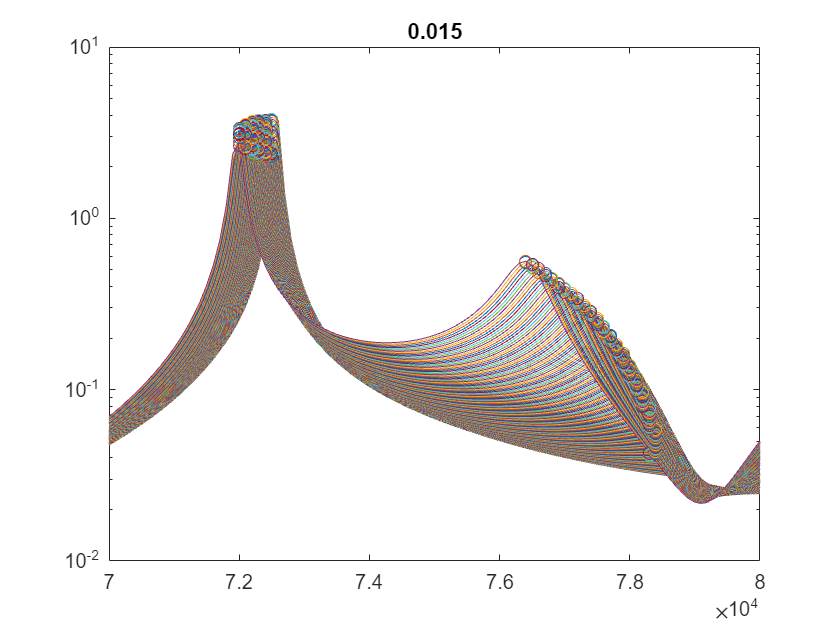

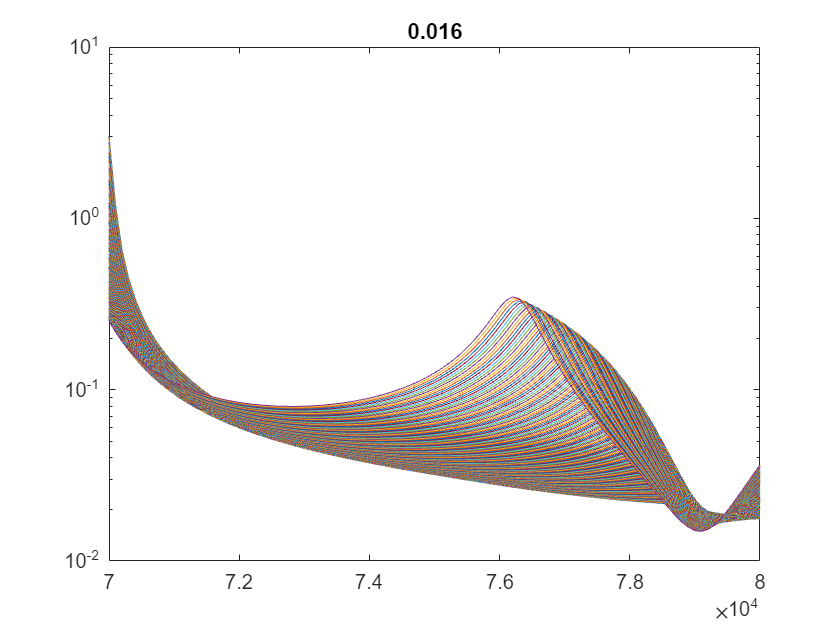

[TF1, P1] = islocalmax(abs(u5_num_w));

for i = 1:10:l3Count
% for i = 4:4
    figure
    % waterfall(l4_water',freq_water',log10(abs(squeeze(u5_num_w(:,i,:)))))

    freqI = squeeze(freq(:,i,:));
    u5I = abs(squeeze(u5_num_w(:,i,:)));

    semilogy(freqI(1,:), u5I)
    hold on
    for j=1:l4Count
        [TF2, P2] = islocalmax(u5I(j,:));

        if(length(freqI(j,TF2))==2)
            scatter(freqI(j,TF2),u5I(j,TF2))
            freqId = freqI(j,TF2);
            u5Id = u5I(j,TF2);
            freqId(2)-freqId(1)
            u5Id(1)*u5Id(2)
        end
    end
    hold off
    % semilogy(squeeze(freq(1,1,:)),abs(squeeze(u5_num_w(:,i,:))))
    % hold on
    % plot(squeeze(freq(TF1(:,i,:))),log10(abs(squeeze(u5_num_w(TF1(:,i,:))))),'r*')
    % hold off
    title(num2str(l3(1,i,1)));
end

% semilogy(squeeze(freq(1,1,:)),log10(abs(squeeze(u5_num_w(:,i,:)))))

TF = islocalmax(abs(u5_num_w),3);
TF_sq = squeeze(reshape(TF, [], 1, freqCount));
freq_sq = squeeze(reshape(freq, [], 1, freqCount));
% semilogy(freq_sq(TF_sq),abs(u5_num_w_sq(TF_sq)))



% hold on
% scatter3(l3(TF), l4(TF), freq(TF),abs(u5_num_w(TF)),abs(u5_num_w(TF)),'filled')
scatter3(l3(TF), l4(TF), freq(TF),5.^abs(u5_num_w(TF)),abs(u5_num_w(TF)),'filled')
colormap(gca,"jet")
hold on
isosurface(l3, l4, freq, imag(detZ_num_w),0)
hold off

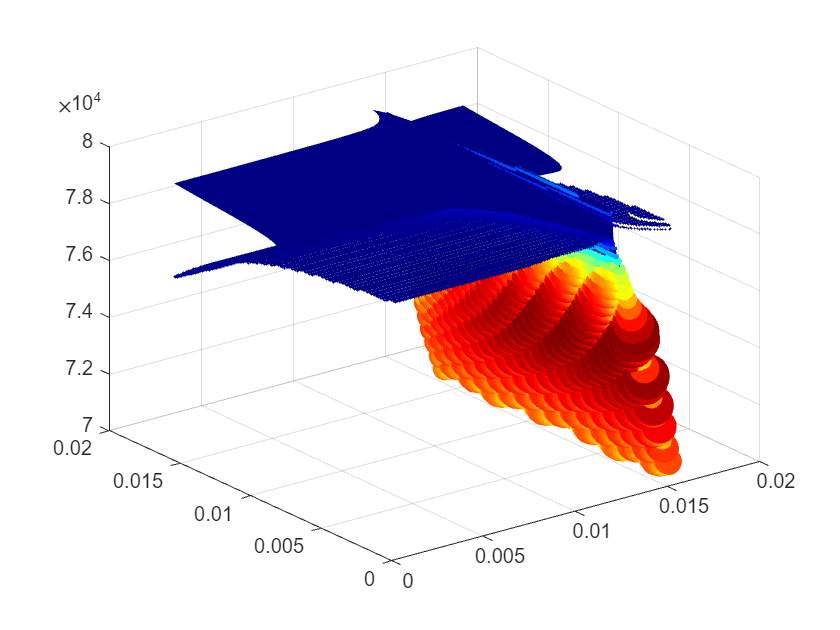

% figure
% p = patch(isosurface(l3, l4, freq, imag(detZ_num_w),0));
% isonormals(l3, l4, freq, imag(detZ_num_w), p)

% isocolors(l3, l4, freq, abs(u5_num_w), p)